**May 27 2023**

# **Predicting ****Conflict**** Errors: Integrating Convolutional Neural Networks and Whole-Brain Modeling of Preparatory Electrophysiological Activity**

**Neda Kaboodvand1, Hanie Karimi, and Behzad Iravani1,2**

1 Department of Clinical Neuroscience, Karolinska Institutet, Stockholm, Sweden.

2 Department of Neurology and Neurological Sciences, Stanford University, Stanford, USA.

Cognitive control refers to humans' ability to regulate, coordinate, and sequence their thoughts and activities in accordance with their behavioral goals. Despite extensive research in the last two decades, the underlying mechanisms of cognitive control in humans are still not fully understood. The neural activity is often difficult to interpret, and the precise mechanisms by which they contribute to cognitive control remained unclear. This could imply that the commonly used analysis methods that are agnostic to theoretical neural-mass dynamics are incapable of fully elucidating the complex dynamics of cognitive control. In this study, a convolutional neural network is utilized to interpret both empirical and theoretical data as part of a multi-modal computational framework that we are building. According to our findings, the insula and angular cortices have the highest predictive value for conflict-error. Yet the whole-brain model only supported the stimulation of the angular gyrus for enhancing cognitive control.

restoredefaultpath % reset matlab path
addpath('C:\MatlabToolboxes\fieldtrip-master\fieldtrip-master')
ft_defaults()

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

addpath(genpath(pwd))

## **Behavioral Data**

**Database1:**

BHV = report_behvaior_dataset1();

total number of individuals: 35 
number of Hit : 204.17 +/- 15.01 
mean rt of Hit : 726.45 +/- 54.70 
number of Error : 21.11 +/- 13.32 
mean rt of Error : 715.15 +/- 95.15 


DS02BHV = load('data\DS02_Behavioral_data.mat');

%% feedback r measurment p
DS02BHV.B.r.fb_a_neg(abs(zscore(DS02BHV.B.r.fb_a_neg(:,1)))>3,1)  = median(DS02BHV.B.r.fb_a_neg(:,1));
DS02BHV.B.r.fb_a_neg(abs(zscore(DS02BHV.B.r.fb_a_neg(:,2)))>3,2)  = median(DS02BHV.B.r.fb_a_neg(:,2));

DS02BHV.B.r.fb_a_pos(abs(zscore(DS02BHV.B.r.fb_a_pos(:,1)))>3,1)  = median(DS02BHV.B.r.fb_a_pos(:,1));
DS02BHV.B.r.fb_a_pos(abs(zscore(DS02BHV.B.r.fb_a_pos(:,2)))>3,2)  = median(DS02BHV.B.r.fb_a_pos(:,2));

DS02BHV.B.r.fb_v_neg(abs(zscore(DS02BHV.B.r.fb_v_neg(:,1)))>3,1)  = median(DS02BHV.B.r.fb_v_neg(:,1));
DS02BHV.B.r.fb_v_neg(abs(zscore(DS02BHV.B.r.fb_v_neg(:,2)))>3,2)  = median(DS02BHV.B.r.fb_v_neg(:,2));

DS02BHV.B.r.fb_v_pos(abs(zscore(DS02BHV.B.r.fb_v_pos(:,1)))>3,1)  = median(DS02BHV.B.r.fb_v_pos(:,1));
DS02BHV.B.r.fb_v_pos(abs(zscore(DS02BHV.B.r.fb_v_pos(:,2)))>3,2)  = median(DS02BHV.B.r.fb_v_pos(:,2));

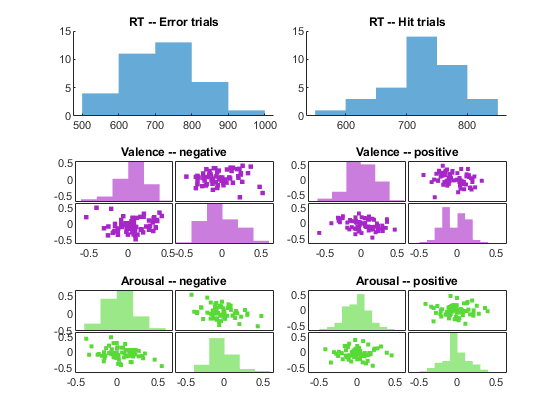

t = tiledlayout(3,4);
clear ax_
ax_(1) = nexttile([1,2]);
histogram(BHV.rtErr,'EdgeColor','none')
title('RT -- Error trials')
box off
ax_(2) = nexttile([1, 2]);
histogram(BHV.rtHit,'EdgeColor','none')
box off
title('RT -- Hit trials')
ax_(3) = nexttile([1, 2]);
[h,ax,BigAx,hhist,pax] =plotmatrix(DS02BHV.B.r.fb_v_neg);%, 'EdgeColor', 'none', 'FaceAlpha', .75)
% camlight
% axis square
% xlim([-.4,.4])
% ylim([-.4,.4])
hhist(1).FaceColor = [.65, 0.15, 0.78];
hhist(1).EdgeColor = 'none';
hhist(2).FaceColor = [.65, 0.15, 0.78];
hhist(2).EdgeColor = 'none';

h(1,2).Color = [.65, 0.15, 0.78];
h(2,1).Color = [.65, 0.15, 0.78];
title('Valence -- negative')
ax_(4) = nexttile([1, 2]);
[h,ax,BigAx,hhist,pax] =plotmatrix(DS02BHV.B.r.fb_v_pos);%, 'EdgeColor', 'none', 'FaceAlpha', .75)
% camlight
% axis square
xlim([-.4,.4])
ylim([-.4,.4])
hhist(1).FaceColor =  [.65, 0.15, 0.78];
hhist(1).EdgeColor = 'none';
hhist(2).FaceColor = [.65, 0.15, 0.78];
hhist(2).EdgeColor = 'none';

h(1,2).Color = [.65, 0.15, 0.78];
h(2,1).Color = [.65, 0.15, 0.78];
title('Valence -- positive')
ax_(5) = nexttile([1, 2]);
[h,ax,BigAx,hhist,pax] =plotmatrix(DS02BHV.B.r.fb_a_neg);%, 'EdgeColor', 'none', 'FaceAlpha', .75)
% % xlim([-.4,.4])
% % ylim([-.4,.4])
hhist(1).FaceColor =  1-[.65, 0.15, 0.78];
hhist(1).EdgeColor = 'none';
hhist(2).FaceColor = 1-[.65, 0.15, 0.78];
hhist(2).EdgeColor = 'none';

h(1,2).Color = 1-[.65, 0.15, 0.78];
h(2,1).Color = 1- [.65, 0.15, 0.78];
title('Arousal -- negative')
% camlight
% axis square
ax_(6) = nexttile([1, 2]);
[h,ax,BigAx,hhist,pax] = plotmatrix(DS02BHV.B.r.fb_a_pos);%, 'EdgeColor', 'none', 'FaceAlpha', .75)
hhist(1).FaceColor =  1-[.65, 0.15, 0.78];
hhist(1).EdgeColor = 'none';
hhist(2).FaceColor = 1-[.65, 0.15, 0.78];
hhist(2).EdgeColor = 'none';

h(1,2).Color = 1-[.65, 0.15, 0.78];
h(2,1).Color = 1-[.65, 0.15, 0.78];

%camlight
% axis square
% xlim([-.4,.4])
% ylim([-.4,.4])
title('Arousal -- positive')

% for i = 1:length(ax)
%     ax(i).FontSize = 12; 
%     ax(i).FontName = 'Arial';
%     if i>2
%         axes(ax(i))
%         if i == 3
%             xlabel('Valence')
%             ylabel('Arousal')
%         end
%         zlim([0, 5])
%         xticks([-.4:.4:.4])
%         yticks([-.4:.4:.4])
%     end
% end
print figures\Behavioral.svg -dsvg -vector

repeated_anova(DS02BHV.B.r)

h = 1

p = 0.0328

ci =     0.0040
    0.0915


stat = struct with fields:
    tstat: 2.1799
       df: 66
       sd: 0.1794


h = 0

p = 0.9681

ci =    -0.0395
    0.0411


stat = struct with fields:
    tstat: 0.0401
       df: 66
       sd: 0.1652


h = 0

p = 0.1616

ci =    -0.0756
    0.0129


stat = struct with fields:
    tstat: -1.4157
       df: 66
       sd: 0.1814


h = 0

p = 0.2430

ci =    -0.0627
    0.0162


stat = struct with fields:
    tstat: -1.1780
       df: 66
       sd: 0.1618


h = 1

p = 0.0318

ci =     0.0048
    0.1016


stat = struct with fields:
    tstat: 2.1937
       df: 66
       sd: 0.1985


h = 0

p = 0.3153

ci =    -0.0241
    0.0738


stat = struct with fields:
    tstat: 1.0119
       df: 66
       sd: 0.2007


h = 0

p = 0.2736

ci =    -0.0778
    0.0224


stat = struct with fields:
    tstat: -1.1039
       df: 66
       sd: 0.2054


h = 1

p = 0.0377

ci =    -0.0824
   -0.0025


stat = struct with fields:
    tstat: -2.1209
       df: 66
       sd: 0.1638


fid = fopen('summaryDS02BHV.txt', 'w');
for f = fieldnames(DS02BHV.B.r)'
    fprintf(fid,'%s valence mean %1.2f sd %1.2f range = [%1.2f, %1.2f]\n', f{:}, mean(DS02BHV.B.r.(f{:})(:,1)), std(DS02BHV.B.r.(f{:})(:,1)), min(DS02BHV.B.r.(f{:})(:,1)), max(DS02BHV.B.r.(f{:})(:,1)));
    fprintf(fid,'%s arousal mean %1.2f sd %1.2f range = [%1.2f, %1.2f]\n', f{:}, mean(DS02BHV.B.r.(f{:})(:,2)), std(DS02BHV.B.r.(f{:})(:,2)), min(DS02BHV.B.r.(f{:})(:,2)), max(DS02BHV.B.r.(f{:})(:,2)));
end
fclose(fid);

## Localizeing time and spcae using CNN

The data from the python scripts are stored in matlab object for further postprocessing and visualizetion 

% clear memory and load the data object
clc
clear all
disp('loading CNN data')

loading CNN data


load data\interp\matlab\CNNData.mat
disp('done!')

done!


**Step 1)** displaying the accuracy for traning, cross validation  and testing 

Data.whats_acc

ans = 0.6673

ans = 0.6964

training : 66.7
 -- losscross-val : 64.2
 -- losstesting : 64.3
 -- loss

**Step 2)** learning rate 

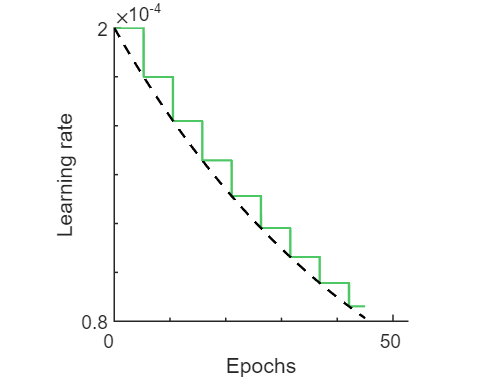

Data.plot_learning_rate(45, 2e-4, .90, 1000, 16)

**Step 3)** plotting the learning curve to show the training and cross validation the accuracy and the performance loss function 

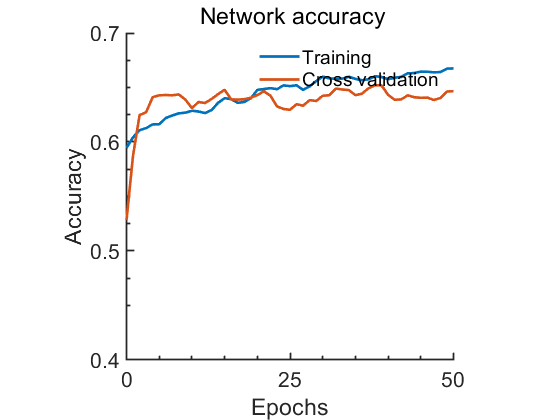

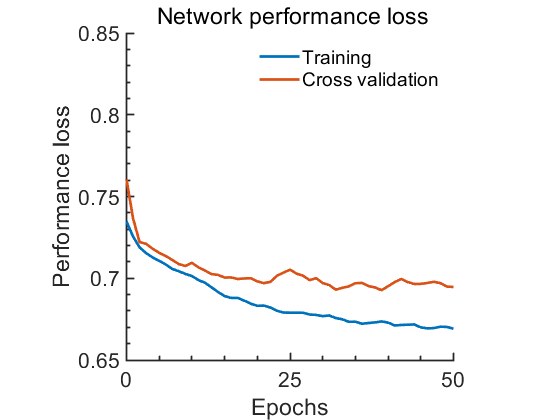

Data.plot_learning_loss

**Step 4)** dispalying mean activation error per channel for class **conflict error**

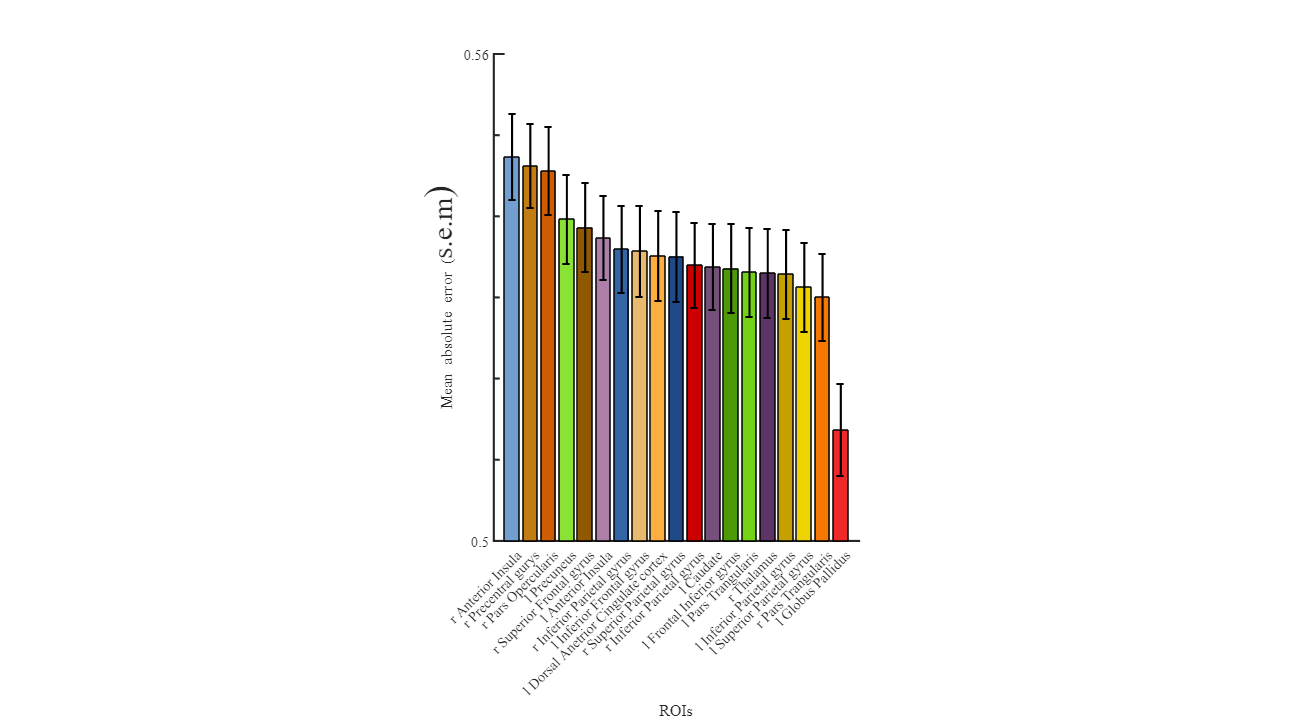

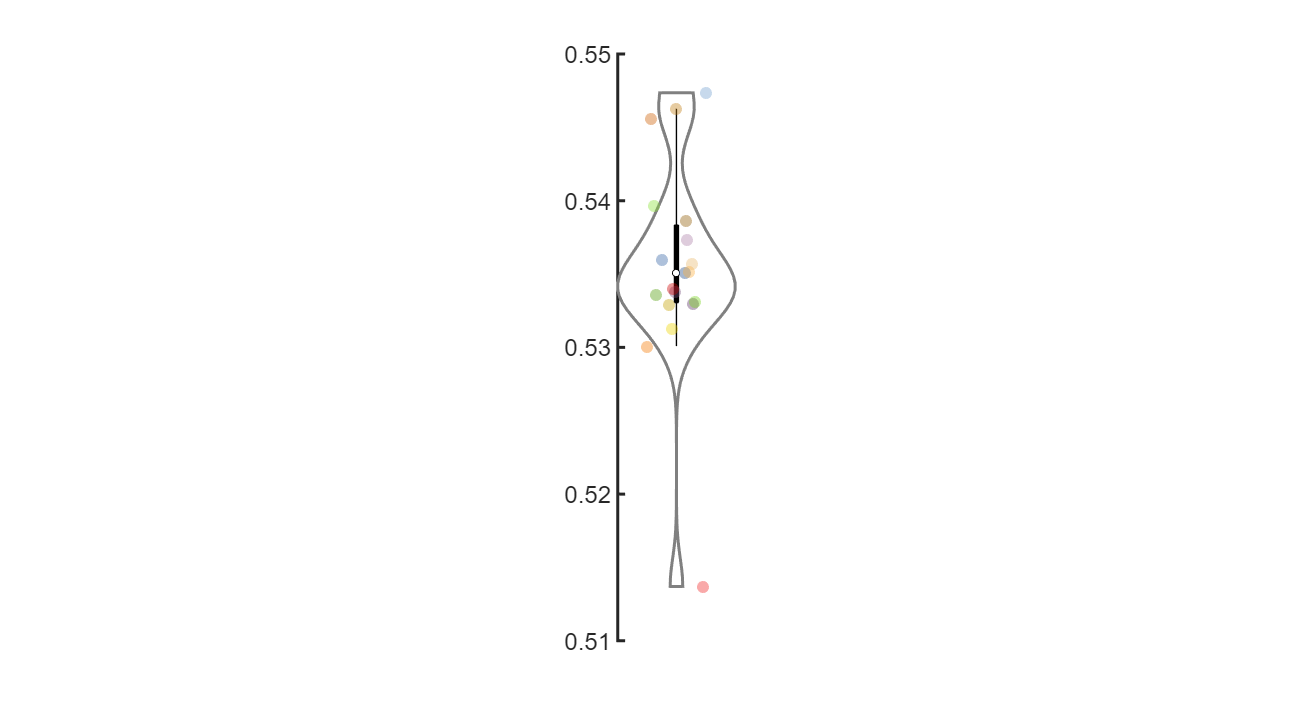

[m,s, ix] = Data.plot_MAE_chan([.50,.56],[.75 1 1], 1);

m = flipud(m); % decending 
s = flipud(s); % decending 
save('OrderMAE.mat', 'ix');

**Step 5) **find the explanability knee

window_size = 3;
knee= find_knee(m, window_size)

knee = 3

hold on, scatter(knee, m(knee)*1.01, 'v')

% permtation test 
% for reproducibility 
rng(1)
nrep = 5e3;
iperm = randi(length(Data.MeanAverageError_chan.MAE_AVG(:,1)), 1,nrep);

t = ((1-Data.MeanAverageError_chan.MAE_AVG(:,1)) -...
        nanmean(1-Data.MeanAverageError_chan.MAE_AVG(iperm,1)))...
        ./ (std(1-Data.MeanAverageError_chan.MAE_AVG(iperm,1)));


fprintf('t = %1.2f \n', t(fliplr(ix(end-2:end)')))

t = 1.73 
t = 1.57 
t = 1.48 


format long
ci = 0;
for i = fliplr(ix(end-2:end)')
    Data.nodeLabel(i,:)
    ci = ci+1;
    p(ci) = mean(Data.MeanAverageError_chan.MAE_AVG(i,1)>=Data.MeanAverageError_chan.MAE_AVG(iperm,1));
    p(ci)
    1-Data.MeanAverageError_chan.MAE_AVG(i,1)
end

ans = 1×6 table
         RegionLabel         Extent        t_value         x     y     z
    _____________________    ______    ________________    __    __    _

    {'r Anterior Insula'}     2022     6.25519990921021    38    18    2


ans =    0.049200000000000


ans = single
   0.5473534


ans = 1×6 table
         RegionLabel          Extent        t_value         x      y     z 
    ______________________    ______    ________________    __    ___    __

    {'r Precentral gurys'}     663      5.16225576400757    38    -14    62


ans =    0.099400000000000


ans = single
   0.5462679


ans = 1×6 table
         RegionLabel          Extent        t_value         x     y    z 
    ______________________    ______    ________________    __    _    __

    {'r Pars Opercularis'}     2022     6.86828422546387    46    8    28


ans =    0.151600000000000


ans = single
   0.5456350


fprintf('p = %1.3f', round(p,3))

p = 0.049p = 0.099p = 0.152

**Step 5) **gradCAM 

% clf
% s2r = Data.plot_grad_cam(Data, ...
%     'C:\Users\behira\OneDrive - Karolinska Institutet\Desktop\Manuscript\CognitiveControl\scripts\data\interp\matlab',...
%     'C:\Users\behira\OneDrive - Karolinska Institutet\Desktop\Manuscript\CognitiveControl\scripts\figures\DS01', true);

**Step 6)** displaying the learned filter for each ROI 

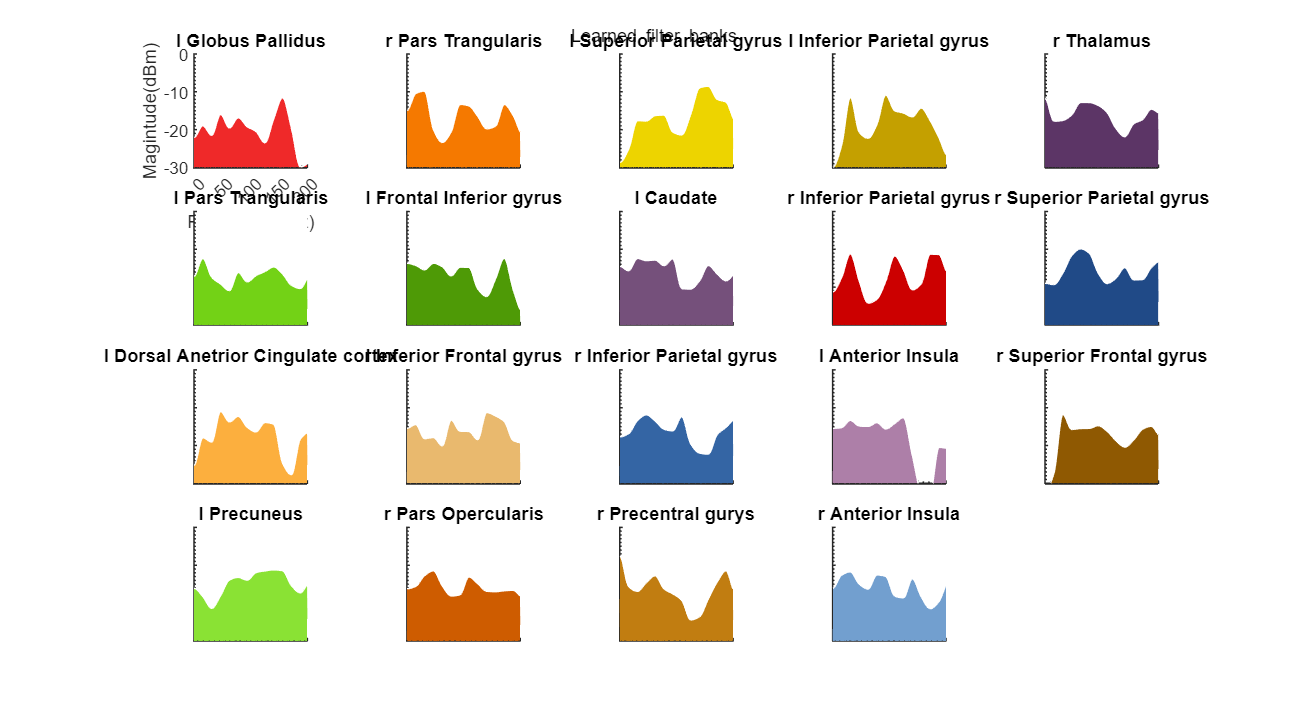

 peaks_f = Data.plot_learned_filters(14, fliplr(ix));

## Time course test sample source filtered by CNN

[b, p, CI, stat]=Data.apply_filter([9,8]);

c =      0


close all
col = Data.getColor();
pl(1) = plot(Data.data_incong_hit_err.data.time(1:length(stat{1, 1}.tstat)),  stat{1, 1}.tstat, 'LineWidth',1.6, 'Color', col(9,:))

pl =   Line with properties:

              Color: [0.447058823529412 0.623529411764706 0.811764705882353]
          LineStyle: '-'
          LineWidth: 1.600000000000000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-1.500000000000000 -1.498000000000000 -1.496000000000000 -1.494000000000000 -1.492000000000000 -1.490000000000000 -1.488000000000000 -1.486000000000000 -1.484000000000000 -1.482000000000000 -1.480000000000000 -1.478000000000000 … ]
              YData: [-3.0590467 -2.3754020 -2.4196332 -1.8243241 -1.3514893 -1.3314846 -1.1322689 -0.1406265 0.1121290 -0.2574918 -0.5787163 -0.5385888 -0.5918074 -0.6714333 -0.5555497 -0.4538861 -0.8305555 -0.5166130 -0.5364704 -0.5923581 … ]

  Show 

hold on
pl(2) = plot(Data.data_incong_hit_err.data.time(1:length(stat{1, 2}.tstat)), stat{1, 2}.tstat, 'LineWidth',1.6,'Color', col(8,:))

pl =   1×2 Line array:

    Line    Line


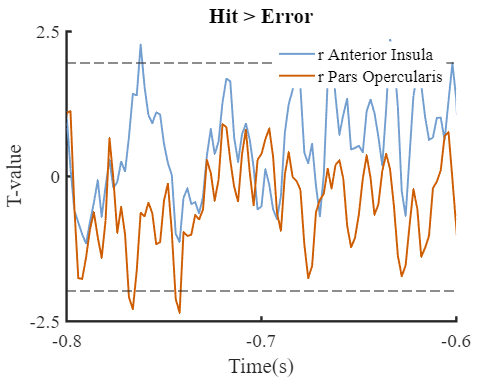

xlim([-.8,-.6])
box off
xticks(-.8:.1:-.6); yticks(-2.5:2.5:2.5)
set(gca, 'FontName', 'Arial Nova Cond', 'FontSize', 16, 'LineWidth', 2)
ylim([-2.5, 2.5])
yline(tinv(.025, stat{1, 1}.df(1)), 'LineStyle', '--'), yline(tinv(.975, stat{1, 1}.df(1)), 'LineStyle', '--')
xlabel('Time(s)')
ylabel('T-value')
title('Hit > Error')
legend(pl, Data.nodeLabel{[9,8],"RegionLabel"}, 'Box', 'off')

The simulated time courses using neural mass model for each stimulation setting Is tested with the trained CNN 

ans =   Axes (\rmDecoding simulated signals by SCNN) with properties:

             XLim: [0 0.030000000000000]
             YLim: [-0.002678872086108 0.600000000000000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.130000000000000 0.164084229063913 0.775000000000000 0.745201455114324]
            Units: 'normalized'

  Show all properties


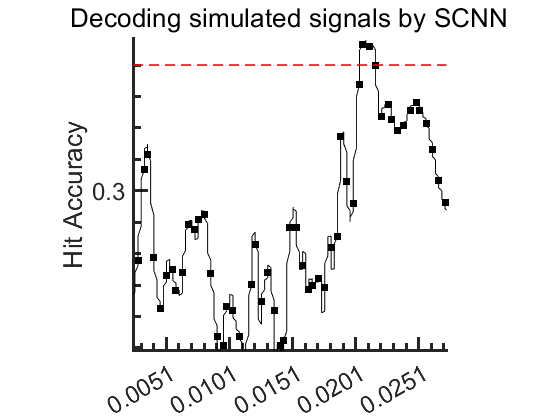

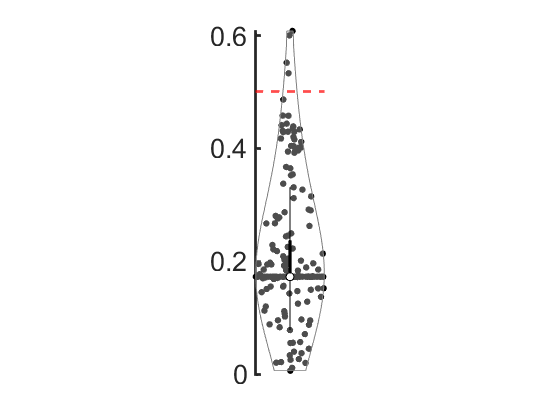

close all
path = {'data\source\python_simulation\C\'; 'data\source\python_simulation'};
%% Construct result_stimulation object 
sine_stimulation_results = results_stimulation(path);  
%% Plot the search parameter 
sine_stimulation_results.plot_parameters();

sine_stimulation_results.report_stat(5e3);

Hieghest acc at c: 0.0214 : t = 3.43, p = 0.005


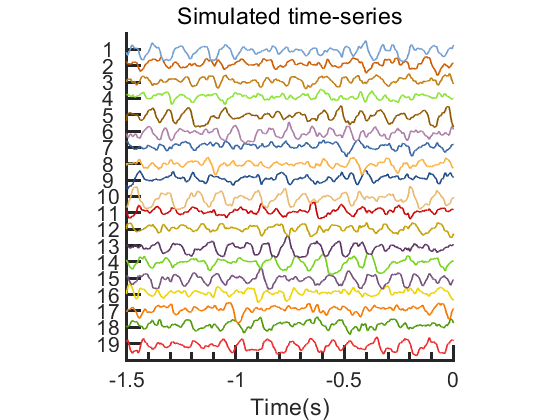

ans =   Axes (\rmSimulated time-series) with properties:

             XLim: [-1.500000000000000 0]
             YLim: [0 20]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.130000000000000 0.143968250278443 0.775000000000000 0.776587307192976]
            Units: 'normalized'

  Show all properties


%% Plot TCs after in silico stimulation 
figure
sine_stimulation_results.plot_stimulatation_inslico_TCs()

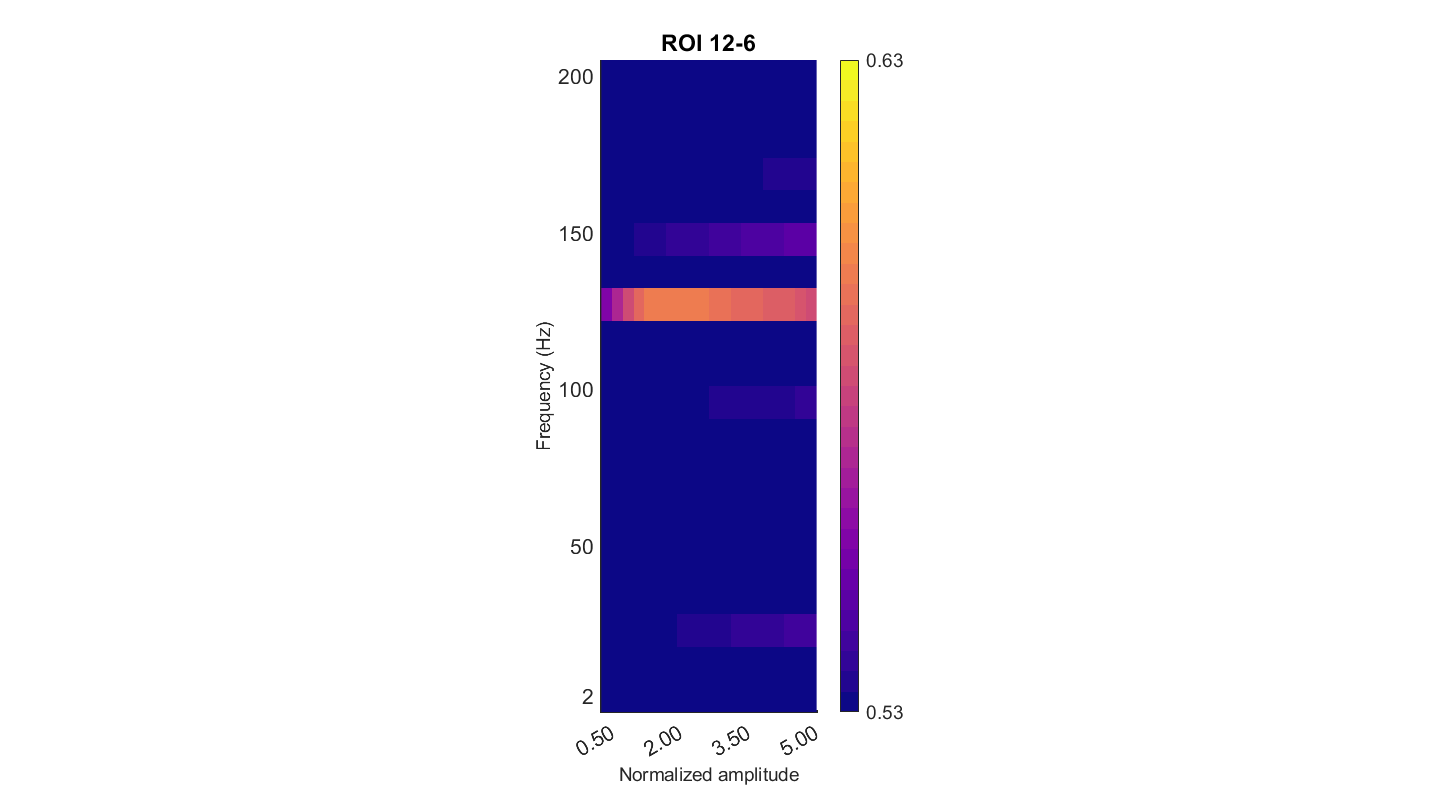

figure('Units','normalized',Position=[0 0 1 1])
sine_stimulation_results.stimulating_three_first_rois(["ROI 12-6"])
pbaspect([.33,1,1])
print -dsvg -vector figures\DS01\DS01_stimulation_heatmap.svg

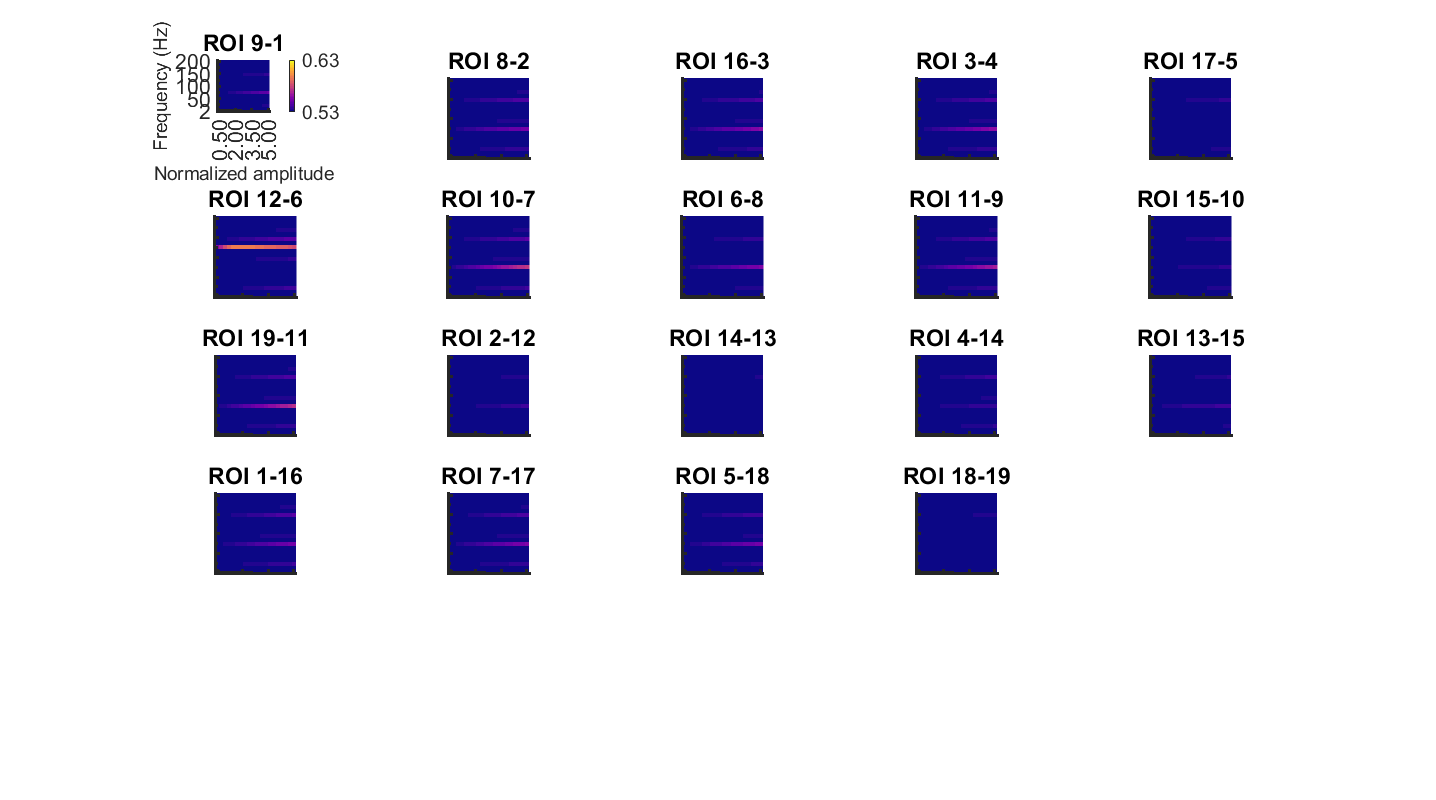

ROIS = [ "ROI 9-1","ROI 8-2", "ROI 16-3", "ROI 3-4", "ROI 17-5" "ROI 12-6"...
    "ROI 10-7", "ROI 6-8", "ROI 11-9", "ROI 15-10", "ROI 19-11", "ROI 2-12", "ROI 14-13", "ROI 4-14", "ROI 13-15",...
    "ROI 1-16", "ROI 7-17", "ROI 5-18", "ROI 18-19"];
figure('Units','normalized',Position=[0 0 1 1])
sine_stimulation_results.stimulating_three_first_rois(ROIS)
print -dsvg -vector figures\DS01\DS01_supp_stimulation_heatmap.svg

[t, p , cirange, stats] = sine_stimulation_results.stimulating_rois_stat(ROIS);
a = linspace(.33,5, 20);
f = linspace(2,200, 20);
[tmax, imx] = max(t,[],'all');
[ind.f,ind.a, ind.roi] = ind2sub(size(t), imx);
fprintf("ROI (%s): t(18) = %1.2f, p = %1.4f @ a= %1.2f f= %1.2f\n", ROIS(ind.roi), t(imx), 2*(1-tcdf(t(imx),18)), a(ind.a), f(ind.f))

ROI (ROI 12-6): t(18) = 4.05, p = 0.0007 @ a= 0.82 f= 127.05


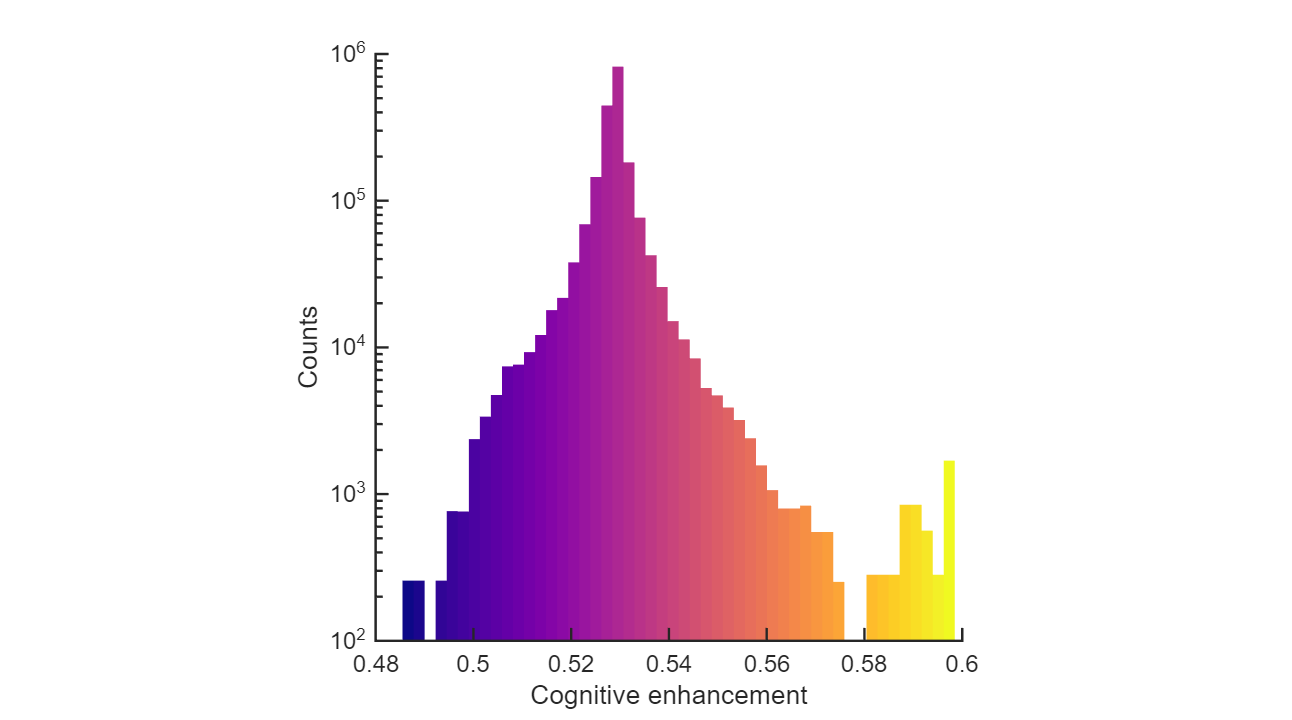

clf
% hold on
% ca = 0 ;
% for A=a
%     ca = ca +1;
%     cf = 0 ;
%     for F = f
%         cf = cf +1;
%             scatter3(A*(ones(1, 5000) + .1*rand(1,5000)-.2), ...
%                 F*(ones(1, 5000) + .1*rand(1,5000)-.2), (squeeze(stats(ca,cf,:)) - mean(squeeze(stats(ca,cf,:))))...
%                 /std(squeeze(stats(ca,cf,:))), 10,'filled', 'MarkerEdgeColor','none', 'MarkerFaceColor', 'r', 'MarkerFaceAlpha', .1)
%     end
% end
numBins = 50;
[n,x] = hist(stats(:),numBins);
h = bar(x,n);
h.EdgeColor = "none";
h.BarWidth = 1;
cmap = plasma(50);

for iBin = 1:numBins
    h.FaceColor = 'flat';
    h.CData(iBin,:) = cmap(iBin,:);
end

ax = gca();
ax.YScale = "log";
ax.FontSize = 20; 
ax.FontName = 'Arial'; 
ax.LineWidth = 2;
ax.TickLength(1) = .02;
box off
axis square
ylabel('Counts')
xlabel('Cognitive enhancement')


print -dsvg -vector figures\DS01\DS01_cognitiveEnhancementHist.svg


clf
ax = sine_stimulation_results.implot(t(:,:,ind.roi),[2,4.5]);
pbaspect([.33,1,1])
cb = colorbar();
ylabel(cb, 'T-value')
axis xy
ax.XAxis.Color = 'w'

ax =   Axes (Statistical map) with properties:

             XLim: [0.381578947368421 5.118421052631579]
             YLim: [-3.210526315789473 2.052105263157895e+02]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.126441241671409 0.110000000000000 0.753784325348785 0.815000000000000]
            Units: 'normalized'

  Show all properties


ax.YAxis.Color = 'w'

ax =   Axes (Statistical map) with properties:

             XLim: [0.381578947368421 5.118421052631579]
             YLim: [-3.210526315789473 2.052105263157895e+02]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.126441241671409 0.110000000000000 0.753784325348785 0.815000000000000]
            Units: 'normalized'

  Show all properties


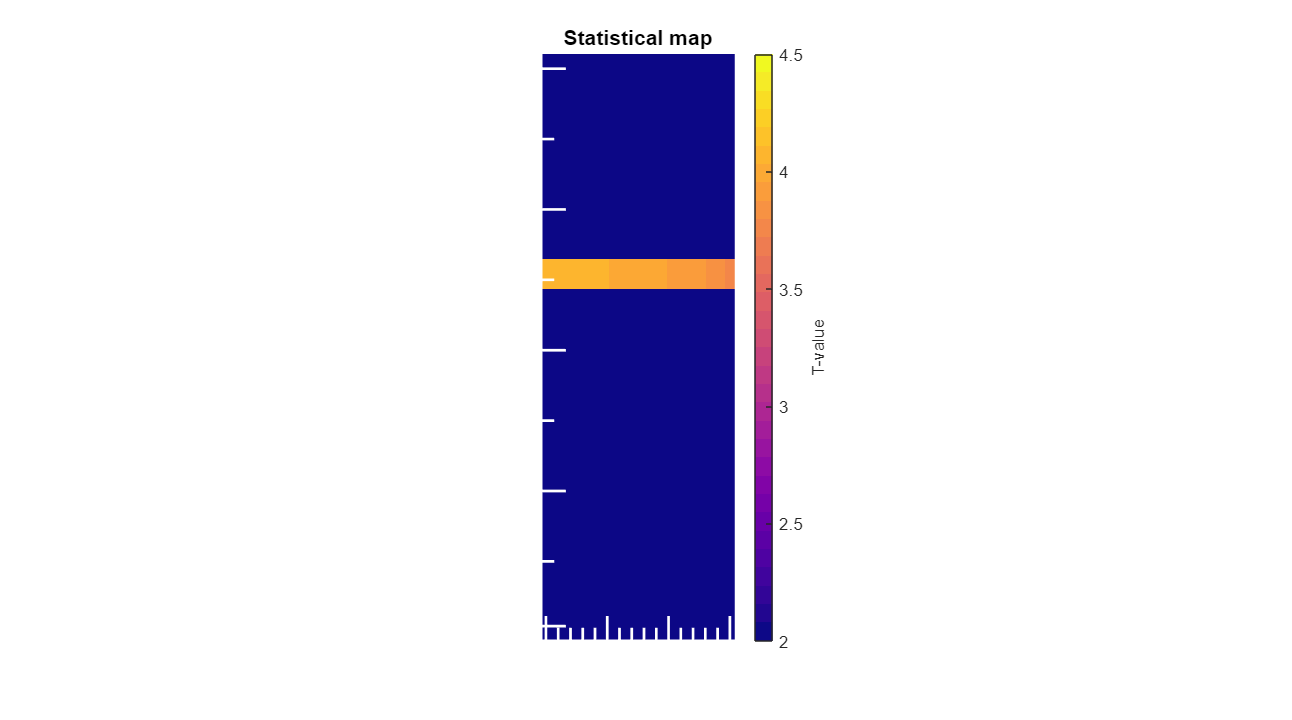

print -dsvg -vector figures\DS01\DS01_stimulation_heatmap_stats.svg



figure
s =sine_stimulation_results.stimulating_traceplot(["ROI 9-1", "ROI 8-2", "ROI 16-3", "ROI 3-4", "ROI 17-5" "ROI 12-6"...
    "ROI 10-7", "ROI 6-8", "ROI 11-9", "ROI 15-10", "ROI 19-11", "ROI 2-12", "ROI 14-13", "ROI 4-14", "ROI 13-15",...
    "ROI 1-16", "ROI 7-17", "ROI 5-18", "ROI 18-19"])

ans =   Axes with properties:

             XLim: [0 20]
             YLim: [-5.350841999053955 15]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.130000000000000 0.110000000000000 0.775000000000000 0.815000000000000]
            Units: 'normalized'

  Show all properties


s = struct with fields:
       mu: 0.5535942
    sigma: 0.0163974
       df: 18
        t: [-1.0809491 0.0132461 1.4271848 1.8214773 -4.2821250 11.9310169 5.8301721 0.6522422 3.0842428 -4.1208429 4.8431497 -3.4268026 -5.3508420 -3.3816774 -3.5962129 0.0874621 0.6882411 -0.1204822 -5.0185494]
        p: [0.2939903 0.9895772 0.1706446 0.0851969 4.4846535e-04 0 1.5974045e-05 0.5224878 0.0063959 6.4182281e-04 1.3053417e-04 0.0030075 4.3749809e-05 0.0033236 0.0020645 0.9312699 0.5000755 0.9054358 8.9168549e-05]
       ci: [0.5456908 0.5614975]


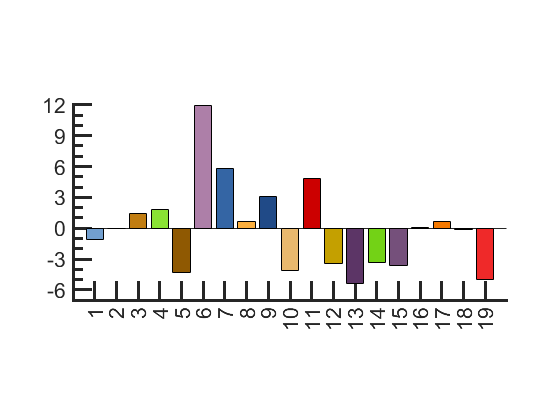

print -dsvg -vector figures\DS01\DS01_stimulation_bar.svg

## Second dataset Pyschophysiology-fMRI data

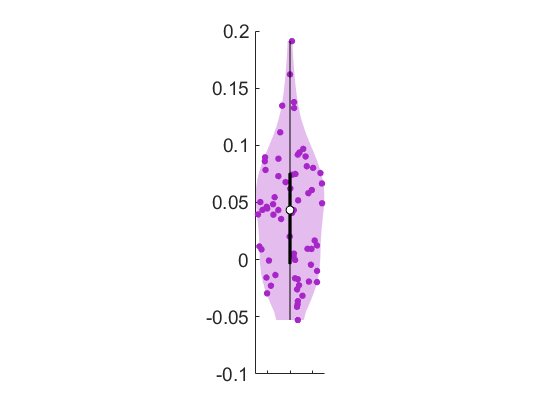

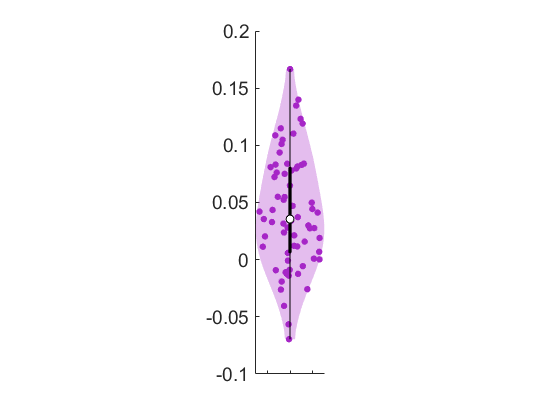

psdat = PSYDAT(struct('valence', 'data\fMRI\DS02\DIM1_EMG'  ,'arousal', 'data\fMRI\DS02\DIM2_SCR'));
psdat.vplot('valence')

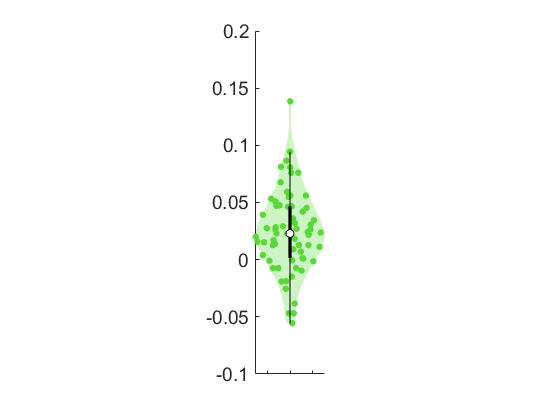

psdat.vplot('arousal')